# Hobbing - Anwendung der Mathematik

## Definition

Modul?

m=3;

al_n= 20;

### Parameter Verzahnung

#### Wälzkreisdurchmesser

d_WZ= 40;

#### Zähnezahlen

z_WZ= 1;
z_WST= 24;

h_f0f =1.4;
h_a0f= 1.17;

### Werkzeuggeometrie

#### Berechnung von Parametern der Werkzeuggeometrie?

[phi_WZ,r_WZ,h_WZ] = WZ(d_WZ, m, al_n, h_a0f, h_f0f, z_WZ);

be =     -7.485984771076686e-02

r_WZ_basis =      1.580000000000000e+01     2.351000000000000e+01     2.351000000000000e+01     1.580000000000000e+01


h_WZ_basis =     -3.884869474110395e+00    -1.078658967917975e+00     1.078658967917975e+00     3.884869474110395e+00


phi_WZ_basis =      1.838711662108477e-02     3.431413515549657e-03    -3.431413515549657e-03    -1.838711662108477e-02


h_WZ_basis =     -3.873989158589616e+00    -1.075637978412799e+00     1.075637978412799e+00     3.873989158589616e+00


phi_WZ =      1.838711662108477e-02     3.431413515549657e-03    -3.431413515549657e-03    -1.838711662108477e-02


r_WZ =      1.580000000000000e+01     2.351000000000000e+01     2.351000000000000e+01     1.580000000000000e+01


h_WZ =     -3.873989158589616e+00    -1.075637978412799e+00     1.075637978412799e+00     3.873989158589616e+00


#### Parametrierung der Transformationsmatrizen

Werte der Transformationsmatrix der Maschine

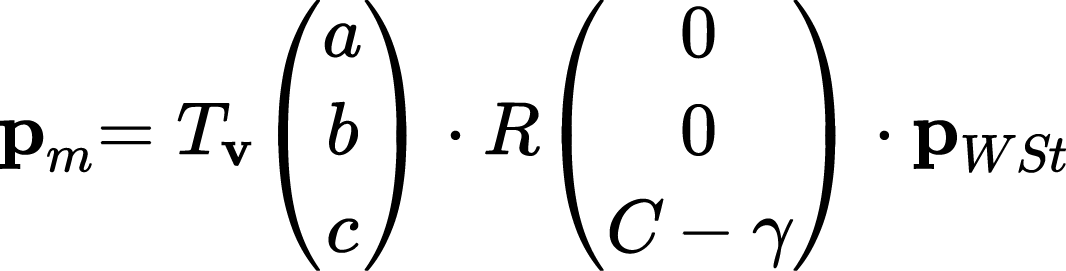

a=0;
b=0;
c=0;
ga=0;

Werte der Transformationsmatrix eines Werkzeugpunktes

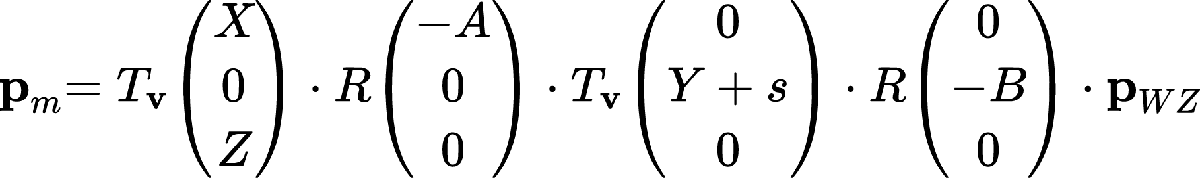

X= m*z_WST/2 + d_WZ/2;
Y=0; 
Z=-5;
Y_shift=0;

#### Winkel A

Vorzeichen:

- doppelter Negativ?

- beim Definieren der Rotationsmatrix wird der Winkel positiv eingeführt

- Rotation ist allerdings mathematisch positiv um x-Achse

A = -atan2(m,d_WZ);

#### Vorschübe?

festhalten (Scherbarths Annäherung?)

fX_WZrad=0;
fY_WZrad=0;

Einheit?

fZ_WZrad= -10/(2*pi);

1/[Zähnezahl] -> Verwendung des Vorschubes so im Simscape Modell?

fC_WSTrad= -1/z_WST;

## CAD Daten des Zahnrads

laden

gear.path = "D:\git\ba\scherbarth";
gear.name = "m3z24h10.stl";
m3z24h10 = stlread(fullfile(gear.path,gear.name));

Koordinaten des Werkstücks in getrennte Variablen

x_WST= m3z24h10.Points(:,1);
y_WST= m3z24h10.Points(:,2);
z_WST= -m3z24h10.Points(:,3);

Soll z-Position

z_soll= -6;

## Berechnung des Verfahrwinkels B

#### Alternativ mit fzero

Formel ist GesamtTM * WZ_zyl?

Problem 1:

- -z_soll nicht in der Formel?

Problem 2:

- warum $cos(A) * sin(B - \phi)$?

- sollte das nicht sein: $cos(A + \phi_{WZ})sin(B)$

p_WST(3)
tfzero = tic;
% fzero(Formel, Startwert)
B= fzero(@(B) Z - c + B*fZ_WZrad + sin(A)*(Y + Y_shift + B*fY_WZrad) + h_WZ(1,2)*sin(A) + r_WZ(1,2)*cos(A)*sin(B-phi_WZ(1,2)) - z_soll, pi)
fprintf('Dauer Lösung mit fzero: %.4f sec.\n',toc(tfzero))

#### Alternativ: Schleife über asin

Herleitung:

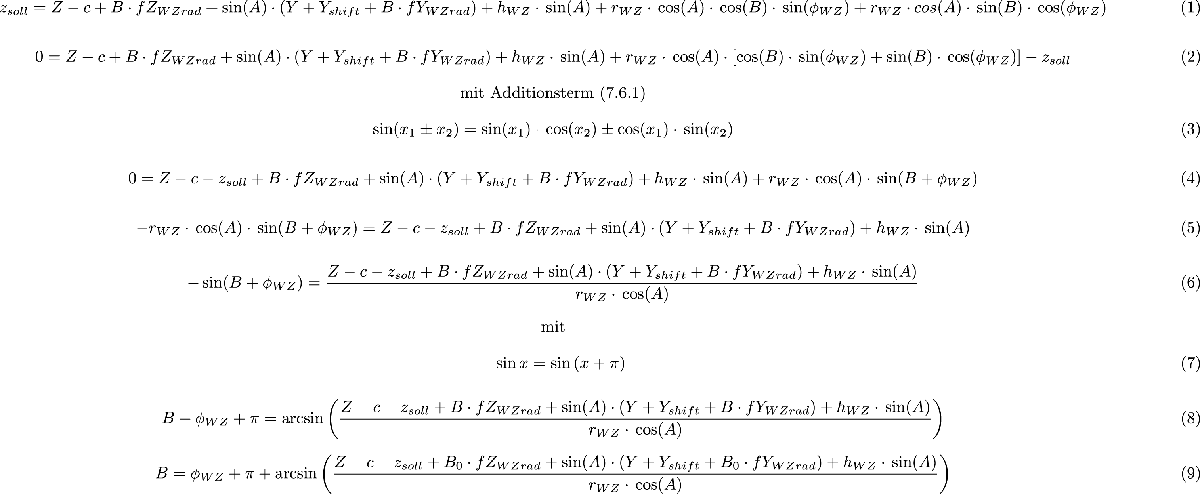

tic
B_0= pi*0.75;
B= phi_WZ + pi + asin((Z - c - z_soll + B_0*fZ_WZrad + sin(A)*(Y + Y_shift + B_0*fY_WZrad) + h_WZ*sin(A))./(r_WZ*cos(A)))
n = 0;
while sum(abs(B-B_0)) > 0.001
    n = n+1;
    conv(n) = sum(abs(B-B_0));
    B_0= B;
    B=  phi_WZ + pi + asin((Z - c - z_soll + B_0*fZ_WZrad + sin(A)*(Y + Y_shift + B_0*fY_WZrad) + h_WZ*sin(A))./(r_WZ*cos(A)))
end
toc

$$ans = Z-c+B\,{\mathrm{fZ}}_{\mathrm{WZrad}}+\sin\left(A\right)\,\left(Y+Y_{\mathrm{shift}}+B\,{\mathrm{fY}}_{\mathrm{WZrad}}\right)+h_{\mathrm{WZ}}\,\sin\left(A\right)+r_{\mathrm{WZ}}\,\cos\left(A\right)\,\cos\left(B\right)\,\sin\left(\varphi_{\mathrm{WZ}}\right)+r_{\mathrm{WZ}}\,\cos\left(A\right)\,\sin\left(B\right)\,\cos\left(\varphi_{\mathrm{WZ}}\right)$$

[figH,axH] = getFigH(2,'Color','white'); set(0,'CurrentFigure',figH(1));
line((1:n),conv,'LineStyle','-','Marker','.')
grid on; set(axH(1),"XTick",1:n); axH(1).Title.String = "Convergence";

B =      2.987639729295744e+00

B=B(1,2)

Dauer Lösung mit fzero: 0.0299 sec.


Berechung Werkzeugposition nach Verfahrwinkel B

x_WZm= X - a + B*fX_WZrad + cos(B)*r_WZ.*cos(phi_WZ) - sin(B)*r_WZ.*sin(phi_WZ); 
y_WZm= cos(A)*(Y + Y_shift + B*fY_WZrad) - b + h_WZ*cos(A) - sin(A)*cos(B)*r_WZ.*sin(phi_WZ) - sin(A)*sin(B)*r_WZ.*cos(phi_WZ); 
z_WZm= Z - c + B*fZ_WZrad + sin(A)*(Y + Y_shift + B*fY_WZrad) + h_WZ*sin(A) + cos(A)*r_WZ.*sin(B-phi_WZ);

B =      3.003187863668458e+00     3.030907953532226e+00     3.017134551312349e+00     2.929059533697358e+00


Berechung Werkstückposition nach Verfahrwinkel B

x_WSTm= x_WST*cos(ga + B*fC_WSTrad) - y_WST*sin(ga + B*fC_WSTrad);
y_WSTm= x_WST*sin(ga + B*fC_WSTrad) + y_WST*cos(ga + B*fC_WSTrad);
z_WSTm= z_WST;

B =      2.936621627640071e+00     2.984664922094184e+00     2.971794276136635e+00     2.869703113305516e+00


B =      2.943511692582736e+00     2.987844203424838e+00     2.974914564663701e+00     2.875891967193221e+00


B =      2.942799013334465e+00     2.987625674470903e+00     2.974699880150410e+00     2.875247136164952e+00


B =      2.942872735059634e+00     2.987640695373295e+00     2.974714651284339e+00     2.875314327512111e+00


## Plotten

set(0,'CurrentFigure',figH(2));

Elapsed time is 0.032433 seconds.


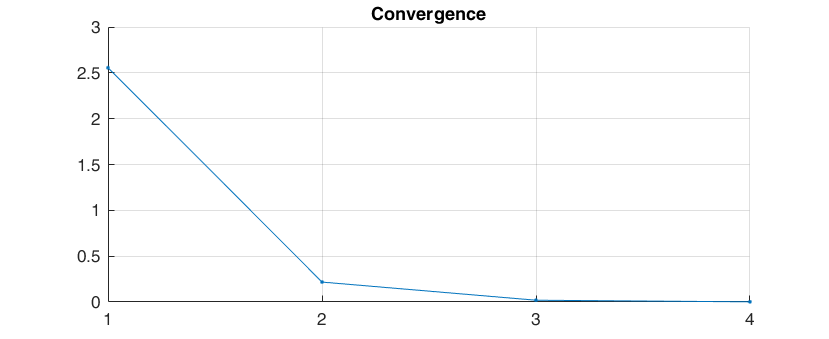

axis vis3d; grid on; grid minor;
hold on;
lim = 43; xlim([-lim lim]); ylim([-lim lim]);

zlim([-10 10]);

B =      2.987640695373295e+00

view([62.5 36.3])

Werkzeug

fill3(x_WZm', y_WZm', z_WZm','r')

Werkstück, rotiert

Zahnrad = triangulation(m3z24h10.ConnectivityList,x_WSTm(:),y_WSTm(:),z_WSTm(:));
trH(1) = trisurf(Zahnrad);
trH(1).FaceColor = 'c';
trH(1).EdgeAlpha = 0.2;

Werkstück, Ausgangsposition

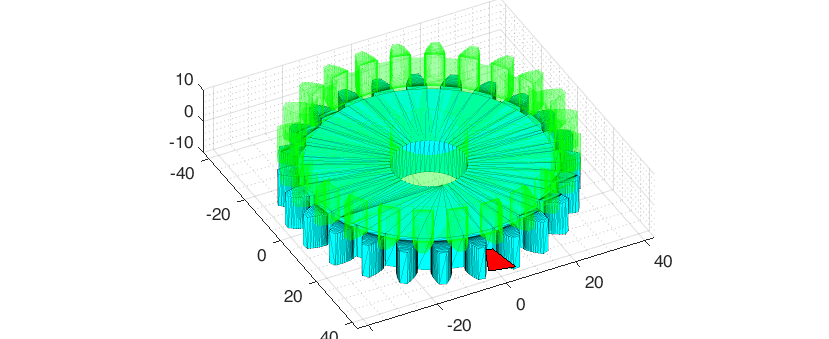

trH(2) = trisurf(m3z24h10);
trH(2).FaceColor ='g';
trH(2).FaceAlpha = 0.2;
trH(2).EdgeColor = 'g';
trH(2).EdgeAlpha = 0.2;